# Leo Berman & Justin Ok Project 4 Code

## Step 0

clear;
data = load("ecg_data.txt");
t = data(:,1);
x = data(:,2);
fs = 1000;

## Step 1

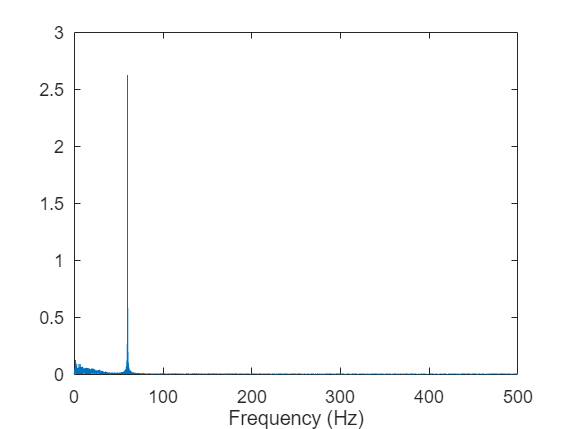

myFFT(x,fs);

## Step 2

### RC Low Pass Filter

R = 6000;
C = .000001;
syms s
Zr = R;
Zc = 1/(s*C);
Vin = 1;
Vout = simplify(Vin*(Zc/(Zr+Zc)))

$$Vout = \frac{500}{3\,s+500}$$

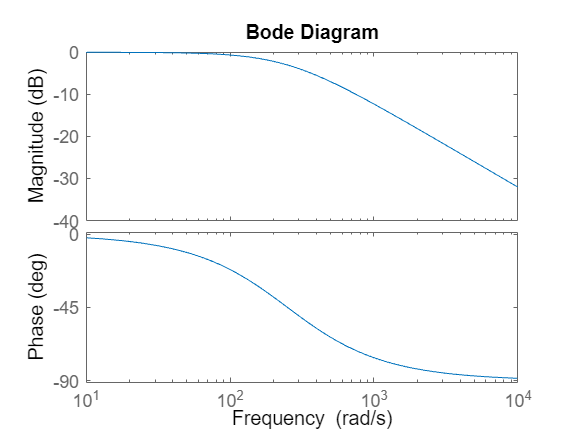

Hf = tf(1,[1/250 1]);
bodeplot(Hf)

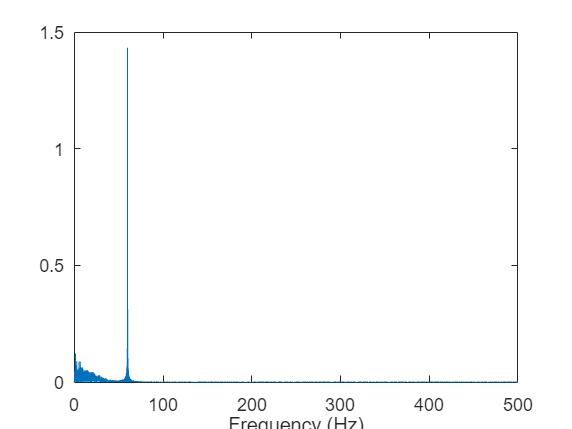

RCFilteredSignal = lsim(Hf,x,t);
myFFT(RCFilteredSignal,fs)

## RLC Band Stop Filter

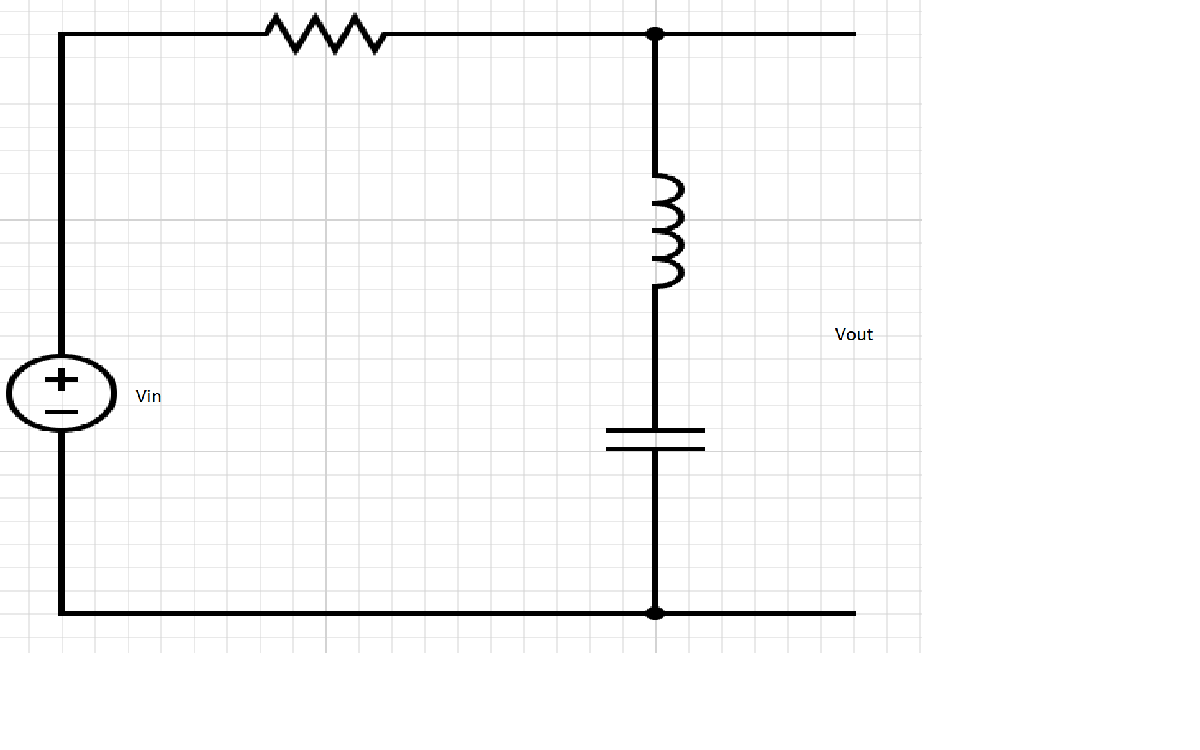

R = 100000;
L = .3;
C = .0001;
10*(1/C)

ans = 100000

syms s
Zr = R;
Zl = s*L;
Zc = 1/(C*s);
Vin = 1;
Vout = simplify((Vin*(Zl+Zc))/(Zr+Zl+Zc))

$$Vout = \frac{3\,s^{2}+100000}{3\,s^{2}+1000000\,s+100000}$$

Hf = tf([L/(10*(1/C)) 0 1],[L/(10*(1/C)) (R*10)/(10*(1/C)) 1])

Hf =
 
     3e-06 s^2 + 1
  --------------------
  3e-06 s^2 + 10 s + 1
 
Continuous-time transfer function.



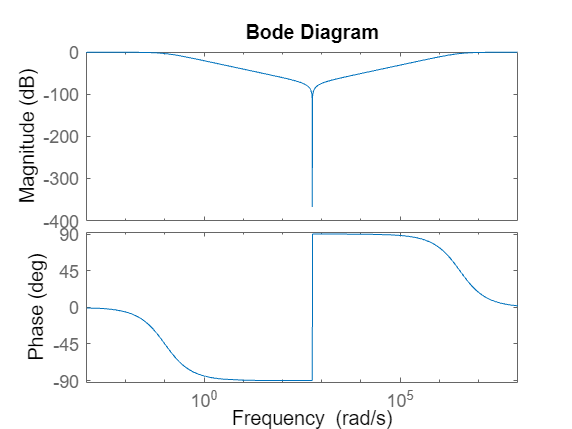

bodeplot(Hf)

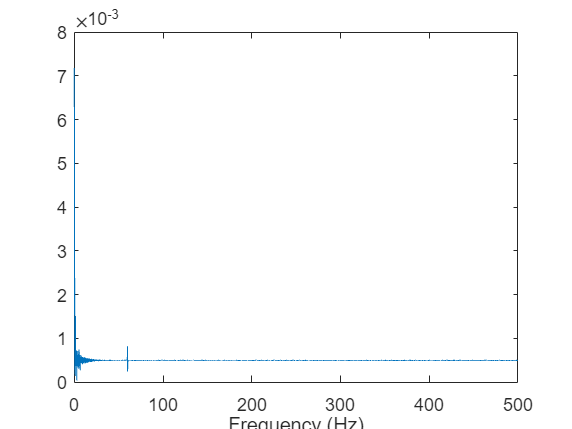

RLCFilteredSignal = lsim(Hf,x,t);
myFFT(RLCFilteredSignal,fs)

## Butter Filter

[num,den] = butter(3,[2*pi*50 2*pi*70],'stop','s')

num = 1.0e+15 *

    0.0000         0    0.0000         0    0.0001         0    2.6381


den = 1.0e+15 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0048    2.6381


Hf = tf(num,den);
ButterFilteredSignal = lsim(Hf,x,t)

ButterFilteredSignal =     0.4959
    0.5465
    0.2569
   -0.0763
   -0.2408
   -0.2207
   -0.1394
   -0.1046
   -0.1167
   -0.1145


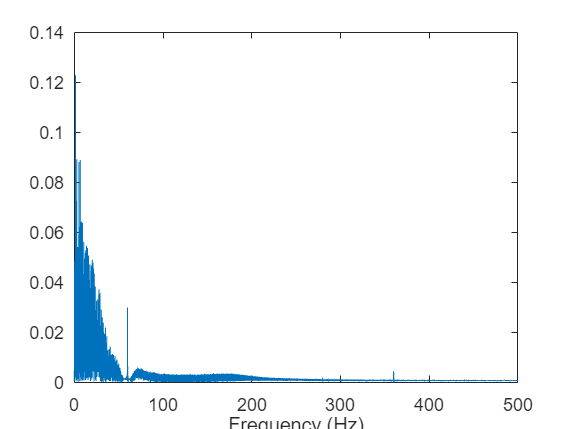

myFFT(ButterFilteredSignal,fs)